    storage part

% clear;
path = 'C:\Users\jzyan\OneDrive\PhDwork\opnet\data\iaap\n7-aap-cs4k-pit6k-cl12k-rr';
% pre = '1k';
extension = '.txt';
file1 = ['-app-time-name' extension];
file2 = ['-app-time-num' extension];
file3 = ['-app-name-delay' extension];

s = 7; %total # of nodes
x = 1; %# of r_i
y = 1; %# of c_i
z = 1; %# of c_{i+1}
lambda = 2453.7*2/s/(s-1);
% lambda = 124.7;
Lambda = 1600;
% tempRatio = 1;
smplIntrv = 60;

% AAP trans storage matrix initialization
[preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n ] = assVar( s, x, y, z  );
[preTransSto, req_n, cont_n]= twoContent(s,x,y,z, preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n);

% conventional trans storage matrix initialization
[conTransSto, N, VStep, MStep, conReq_n, conCont_n] = genTransMatrixSto(s, x, y, z, lambda);
conCont_n = conCont_n +1;
toCont = [2, 1];
indexsum = cumsum(0:(s-2));


pre = num2str(Lambda);
% pre = '1600';
% [path, pre, file2]
rawdat = importdata([path, pre, file2]);

esto = rawdat.data;
rawdat = importdata([path, pre, file1]);
esto = [esto rawdat.data(:,2)];
% esto=[];
rawdat = importdata([path, pre, file3]);
cdelay = rawdat.data(:,2);

testSize = ceil(Lambda/lambda);

% conventional initial dist initialization
conInit = zeros(1,size(conTransSto,1));
conInit(1) = 1;

% AAP initial dist initialization
preInit = zeros(1,size(preTransSto,1));
% init(twoContentTrPos(1,1,1, transitPos, absorbPos )) = 1;

state01 = 0;

for k = 1:5
    %simulation
    [~, conBinVal,   conFin]  = delayPDFsto(conTransSto,    conInit, testSize, conCont_n,  lambda);
    [~, binVal2,     preFin]  = delayPDFsto(preTransSto,    preInit, testSize, cont_n(2,:)', lambda);
    [t, binVal1 ]             = delayPDFsto(preTransSto,    preInit, testSize, cont_n(1,:)', lambda);

%     f = figure();
%     plot(preInit,'Displayname','init');
%     hold on;
%     plot(preFin,'Displayname', 'fin');
%     plot(state01,'Displayname', 'state01');
% 
%     plot(cont_n(2,:)/10, 'Displayname', 'b_i+1');
%     plot( (cont_n(2,:)+cont_n(1,:)) /10, 'Displayname', 'c_i');
%     legend('show');

%     temp = preFin*cont_n(2,:)' + conFin*(conCont_n);
    disp(sum(preFin)+sum(conFin)+sum(state01));
    [preInit, conInit, state01] = nextInit_v2(s, preTransSto, preFin, cont_n, transitPos, ...
        absorbPos, conTransSto, conFin, conCont_n, indexsum, state01);
    disp(sum(preInit)+sum(conInit)+sum(state01));
%     temp = temp - preInit'*(cont_n(2,:) + cont_n(2,:) )' - conFin*(conCont_n);
        
    preInit = preInit'; 
    conInit = conInit'; 
end

    1.0000



    1.0000



     1



     1



     1



    1.0000



    1.0000



    1.0000



     1



     1



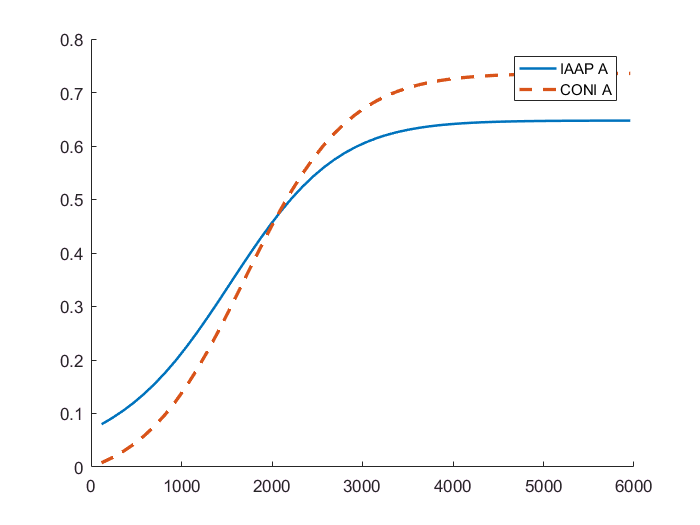


testSize = ceil( 6000/lambda);
[~, finConBinVal]  = delayPDFsto(conTransSto,   conInit, testSize, conCont_n,    lambda);
[~, finBinVal2]    = delayPDFsto(preTransSto,   preInit, testSize, cont_n(2,:)', lambda);
[fint, finBinVal1] = delayPDFsto(preTransSto,   preInit, testSize, cont_n(1,:)', lambda);
finS01 = ones(1,testSize-1)*state01;
% figure;
% % plot(t, binVal1/(s-1), 'DisplayName', 'ci');
% hold on; 
% plot(t, binVal2/(s-1), 'DisplayName', 'bi+1');
% plot(t, conBinVal/(s-1), 'DisplayName', 'con_i');

% hold off;

% figure;
% 
% combindedBin = [(binVal2+conBinVal) (finBinVal1 + finBinVal2 + finConBinVal+finS01)];
% plot([t fint+max(t)], (combindedBin-1)/(s-1),...
%     'DisplayName', 'AAP-A','LineWidth',1.5);
figure;hold on;
combindedBin = (finBinVal1 + finBinVal2 + finConBinVal+finS01);
plot(fint, (combindedBin-1)/(s-1),...
    'DisplayName', 'IAAP A','LineWidth',1.5, 'LineStyle', '-', 'Color', [0 0.45 0.74]);

% CON storage ratio 
conini = zeros(1,size(conTransSto,1));conini(1) = 1;
[t, conBinVal ] = delayPDFsto( conTransSto, conini, testSize, conCont_n, lambda);
plot(t,(conBinVal-1)/(s-1),'DisplayName', 'CONI A','LineWidth',2,'LineStyle','--', 'Color', [0.85 0.33 0.1]);
legend('show');

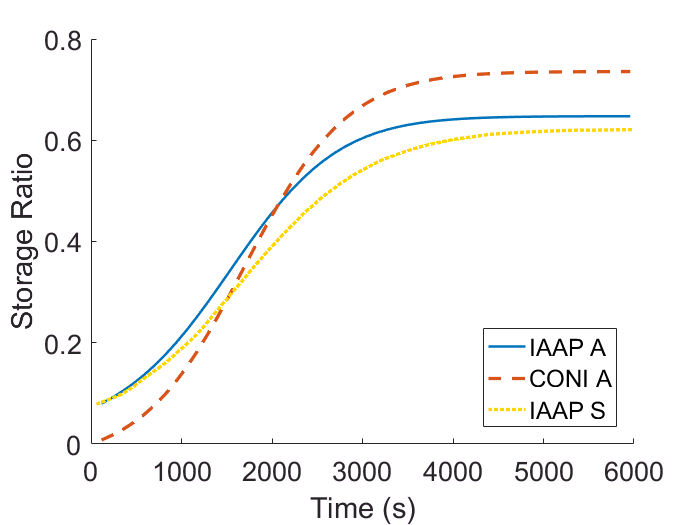

con_m = content_num_process(esto,smplIntrv);
econ = con_m/(s-1);
tmax = 1:ceil(max(t)/smplIntrv); %6000 s for simulated data
% tmax = 1:floor(10000/smplIntrv); %pre set time length for simulated data 
plot( (tmax)*smplIntrv , econ(tmax), 'DisplayName', 'IAAP S','LineWidth',2,'LineStyle',':', 'Color', [1 0.84 0] );
legend('off');
legend('show','Location','southeast');
xlabel('Time (s)');
ylabel('Storage Ratio');
set(gca,'FontSize',16);


%get varience
inter_simu = interp1((tmax)*smplIntrv , econ(tmax) ,fint);
sumtmp = (inter_simu -(combindedBin-1)/(s-1)).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_iaap = mean( sumtmp );
disp( dist_iaap );

    0.0020




sumtmp = (inter_simu -(conBinVal-1)/(s-1)).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_coni = mean( sumtmp );
disp( dist_coni );

    0.0102



delay part


a = 1;b = 1; c = 1;  e = s*(s-1)/2;
test_size = ceil(6000/lambda);
[trans,~] = genTransMatrix(s, a, b, c, lambda);

figure; hold on;
delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    

     1



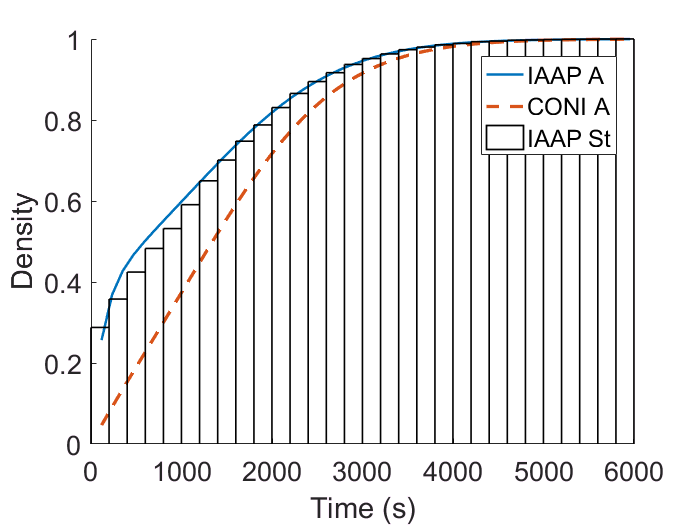

[prepdf, binVal ] = delayCDF_v3( trans, delayInit, test_size, e, lambda );
plot((1:test_size-1)*lambda,prepdf, 'DisplayName', 'IAAP A','LineWidth',1.5,'Color', [0 0.45 0.74]); 

ini = zeros(1,size(trans,1));ini(1) = 1;
[ggpdf, binVal ] = delayCDF_v3( trans, ini, test_size, e, lambda );
plot((1:test_size-1)*lambda, ggpdf, 'DisplayName', 'CONI A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 

ccdf = histogram(cdelay,'BinWidth',200,'Normalization','cdf','DisplayName','IAAP St',...
    'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
xlabel('Time (s)');
ylabel('Density');
legend('show');
set(gca,'FontSize',16)


%get varience
inter_ggpdf = interp1( (1:test_size-1)*lambda , ggpdf , ccdf.BinEdges+ccdf.BinWidth/2); 
sumtmp = (inter_ggpdf(1: (size(inter_ggpdf, 2)-1) ) -ccdf.Values).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_conid = mean( sumtmp );
disp( dist_conid );

    0.0112




inter_prepdf = interp1( (1:test_size-1)*lambda , prepdf , ccdf.BinEdges+ccdf.BinWidth/2); 
sumtmp = (inter_prepdf(1: (size(inter_prepdf, 2)-1) ) -ccdf.Values).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_iaapd = mean( sumtmp );
disp( dist_iaapd );

   3.5093e-04



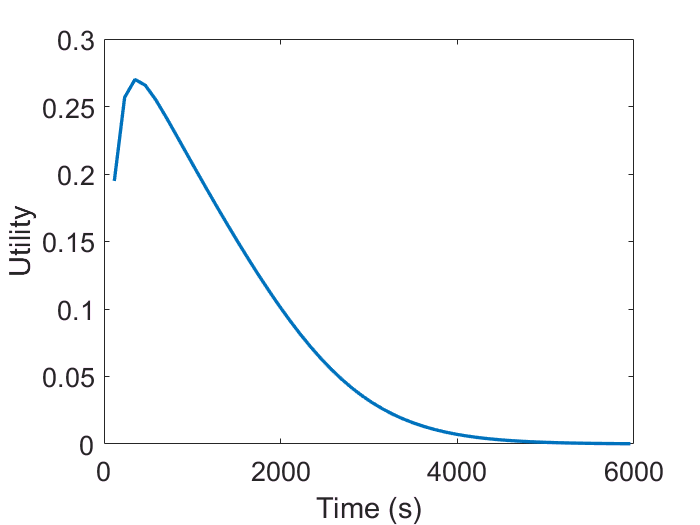

     gain = - ggpdf + prepdf;
     cost = - conBinVal/(s-1) + combindedBin/(s-1);
     prftchU = gain .* (1-cost);
     figure;
     plot(( 1:(test_size-1) )*lambda, prftchU,'DisplayName',['R^{-1}=' num2str(Lambda)],'LineWidth',2); 
     xlabel('Time (s)');
    ylabel('Utility');
    set(gca,'FontSize',16)

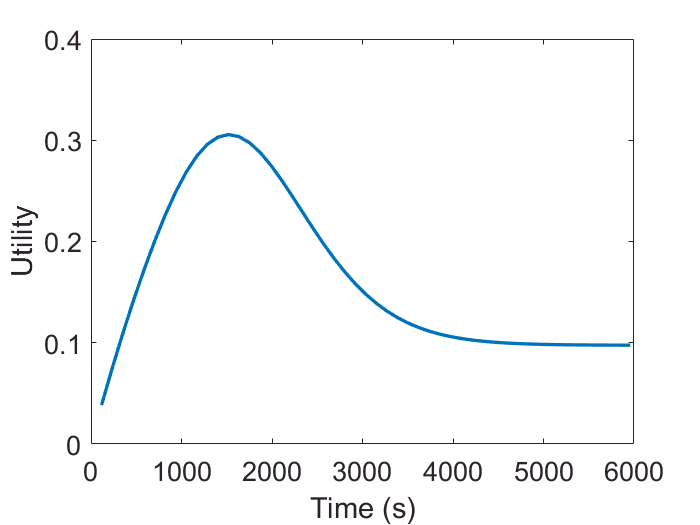

     gain = ggpdf;
     cost = conBinVal/(s-1);
     prftchU = gain .* (1-cost);
     figure;
     plot(( 1:(test_size-1) )*lambda, prftchU,'DisplayName',['R^{-1}=' num2str(Lambda)],'LineWidth',2); 
     xlabel('Time (s)');
    ylabel('Utility');
    set(gca,'FontSize',16)

    %original setting is test_size = ceil(6000/lambda); and the bin width is 200
    

% lambda_r = lambda;
% i = 0;
% alpha = 4;
% stdc = 0;
% stdp = 0;
% 
% for i = 1:50
%     ini = zeros(1,size(trans,1));ini(1) = 1;
%     [ggpdf, binVal ] = delayCDF_v3( trans, ini, test_size, e, lambda_r );
%     gggpdf = [];
% 
%     for i = round((ccdf.BinEdges+ccdf.BinWidth/2) /lambda_r)
%         if (i > size(ggpdf,2))
%             break;
%         end
%         gggpdf = [gggpdf ggpdf(i)];
%             
%     end
%     gggpdf = gggpdf(1:size(ccdf.Values, 2));
%     
%     stdc = sum(((gggpdf - ccdf.Values) - mean((gggpdf - ccdf.Values))).^2);
%     stdc
%     stdp
%     if stdc >= stdp
%         alpha = alpha*-1;
%     end
%     lambda_r = lambda_r + alpha;
%     stdp = stdc;
%     
%     gggpdf
%     lambda_r
% end
% 
% lambda_r
% a = 1;b = 1; c = 1;  e = s*(s-1)/2; lambda = lambda_r;
% [trans,~] = genTransMatrix(s, a, b, c, lambda);
% 
% figure; hold on;
% delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    
% [prepdf, binVal ] = delayCDF_v3( trans, delayInit, test_size, e, lambda );
% plot((1:test_size-1)*lambda,prepdf, 'DisplayName', 'IAAP A','LineWidth',1.5,'Color', [0 0.45 0.74]); 
% 
% ini = zeros(1,size(trans,1));ini(1) = 1;
% [ggpdf, binVal ] = delayCDF_v3( trans, ini, test_size, e, lambda );
% plot((1:test_size-1)*lambda, ggpdf, 'DisplayName', 'CONI A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 
% 
% ccdf = histogram(cdelay,'BinWidth',100,'Normalization','cdf','DisplayName','IAAP St',...
%     'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
% xlabel('Time (s)');
% ylabel('Density');
% legend('show');
% set(gca,'FontSize',16)